Kris Keillor

Commy Sys Lab 4

Static non-linearities and mixers 

Exercise 1. Non-linearity

Results

(a)

With f=100, fs=200, cos wave only yielded minima and maxima; was read as DC when rectified.

With f=100, fs=2000, large DC current was registering as well as diminishing spikes symmetrical about the origin.

fs = 2000;
Ts = 1/fs;
t = Ts:Ts:(2*pi);
f = 100;
inputs = 2 * pi * f .* t;
xt = cos(inputs);
Xf = abs(fftshift(fft(xt)));

% Frequency plot (same for unchanged & rectified)
N = length(Xf);
f_spec = [-N/2:1:(N/2)-1]*fs/N;

% rectification
xt_rectified = abs(xt);
Xf_rect = fftshift(abs(fft(xt_rectified)))

Xf_rect = 	1.0e+03 *

    0.1988    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


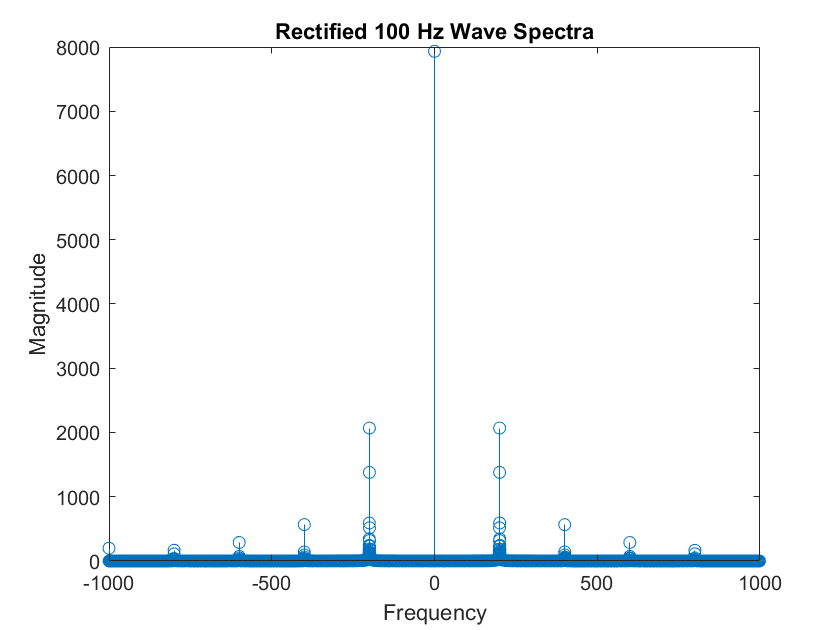


figure(1);
stem(f_spec, Xf_rect);
title("Rectified 100 Hz Wave Spectra");
xlabel("Frequency");
ylabel("Magnitude");

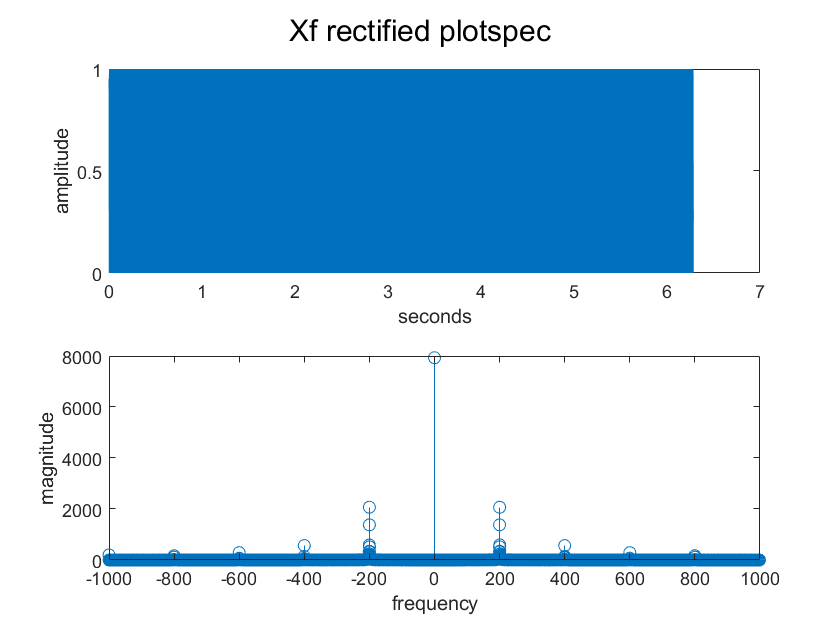


figure(2);
plotspec(xt_rectified, Ts);
sgtitle("Xf rectified plotspec");

(b) 100 & 125 hertz waves constructive 

fs = 2000;
Ts = 1/fs;
t = Ts:Ts:2*pi;

f1 = 100;
f2 = 125;
s1 = cos(2*pi*f1.*t);
s2 = cos(2*pi*f2.*t);
x = abs(s1 + s2);

figure(3);
subplot(2,1,1);
plot(t, x);
xlim([0 2*pi]);
xlabel("time");
ylabel("amplitude");

Xf = fftshift(abs(fft(x)))

Xf = 	1.0e+04 *

    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


N = length(t)

N = 12566

f_axis = [-N/2:1:(N/2)-1]*fs/N

f_axis = 	1.0e+03 *

   -1.0000   -0.9998   -0.9997   -0.9995   -0.9994   -0.9992   -0.9990   -0.9989   -0.9987   -0.9986   -0.9984   -0.9982   -0.9981   -0.9979   -0.9978   -0.9976   -0.9975   -0.9973   -0.9971   -0.9970   -0.9968   -0.9967   -0.9965   -0.9963   -0.9962   -0.9960   -0.9959   -0.9957   -0.9955   -0.9954   -0.9952   -0.9951   -0.9949   -0.9947   -0.9946   -0.9944   -0.9943   -0.9941   -0.9940   -0.9938   -0.9936   -0.9935   -0.9933   -0.9932   -0.9930   -0.9928   -0.9927   -0.9925   -0.9924   -0.9922


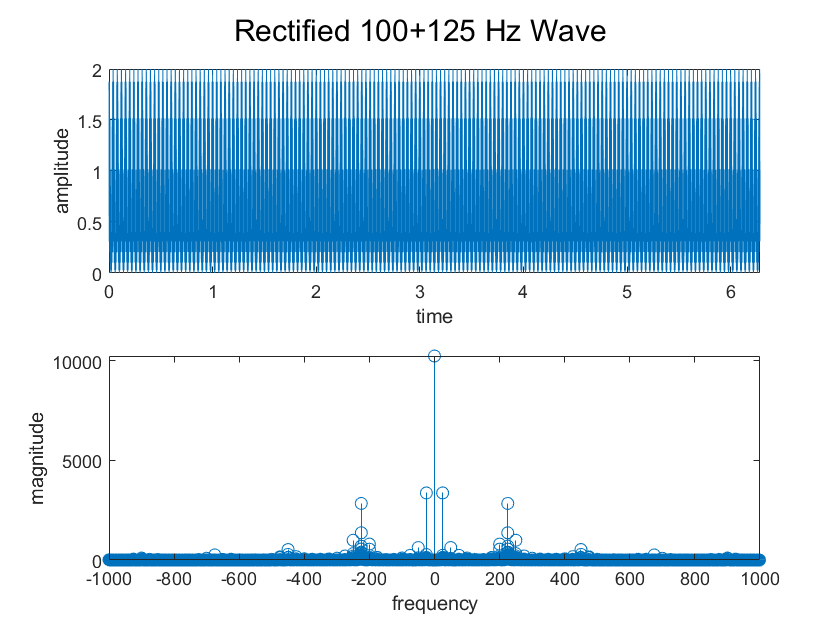


subplot(2,1,2);
stem(f_axis, Xf);
xlabel("frequency");
ylabel("magnitude");
sgtitle("Rectified 100+125 Hz Wave")

(c) 110 and 200 Hz waves constructive. Predict which waves will be present for any f1 and f2. 

Same results for 

fs = 2000;
Ts = 1/fs;
t = Ts:Ts:2*pi;
f1 = 110;               % sig1 freq in Hz
samp1 = 2*pi*f1.*t;     % sig1 sample times in rad/s
s1_wave = cos(samp1);    % signal 1

f2 = 200;               % sig2 freq in Hz
samp2 = 2*pi*f2.*t;     % sig2 sample times in rad/s
s2_wave = cos(samp2);    % signal 2

xt = s1_wave + s2_wave;  % input signals
xt_rect = abs(xt);      % rectified input signals

% mine - one period
t_i200 = t(:,1:200);
xt_i200 = xt_rect(:,1:200);
Xf = abs(fftshift(fft(xt_i200)));    % DFT
N = length(xt_i200);
f_range = [-ceil(N/2):1:ceil(N/2)-1].*(fs/N) % DFT bins

f_range =        -1000        -990        -980        -970        -960        -950        -940        -930        -920        -910        -900        -890        -880        -870        -860        -850        -840        -830        -820        -810        -800        -790        -780        -770        -760        -750        -740        -730        -720        -710        -700        -690        -680        -670        -660        -650        -640        -630        -620        -610        -600        -590        -580        -570        -560        -550        -540        -530        -520        -510


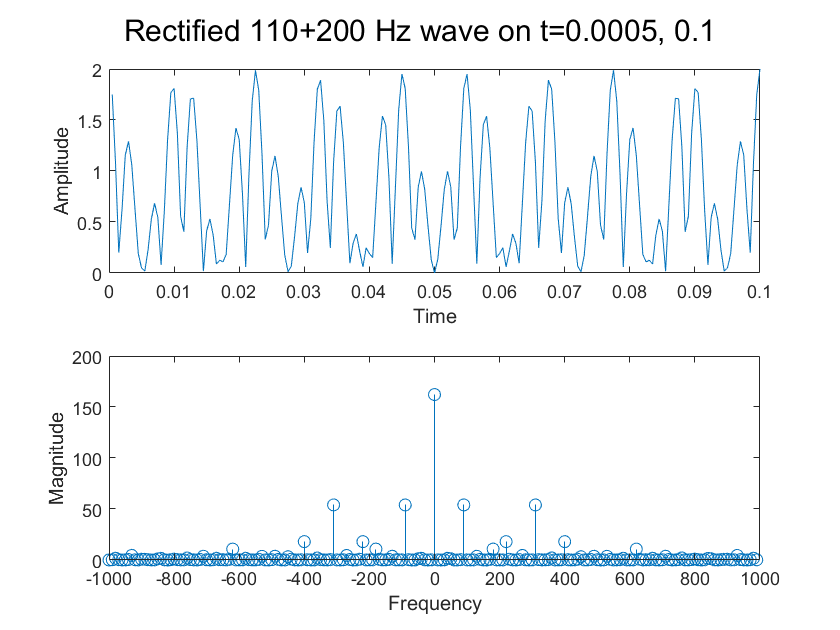


figure(5);
subplot(2,1,1);
plot(t_i200, xt_i200);
xlabel("Time");
ylabel("Amplitude");

subplot(2,1,2);
stem(f_range, Xf);
xlabel("Frequency");
ylabel("Magnitude");
sgtitle("Rectified 110+200 Hz wave on t="+Ts+", "+200*Ts)

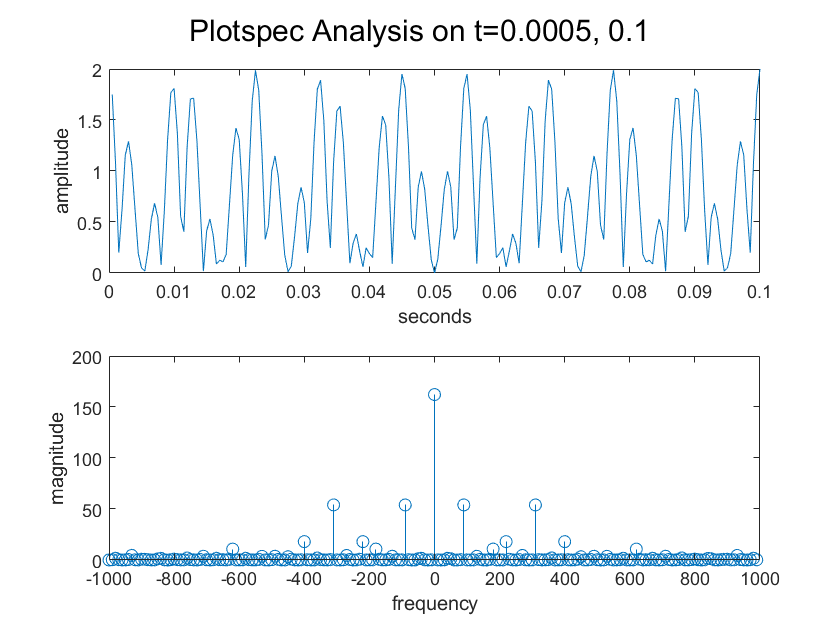


% Theirs - one period 
figure(6);
plotspec(xt_i200, Ts);
sgtitle("Plotspec Analysis on t=" + Ts + ", " + 200*Ts);


% Mine - full time 
figure(7);
Xf = abs(fftshift(fft(xt_rect)));    % DFT
N = length(xt);
f_range = [-ceil(N/2):1:ceil(N/2)-1].*(fs/N) % DFT bins

f_range = 	1.0e+03 *

   -1.0000   -0.9998   -0.9997   -0.9995   -0.9994   -0.9992   -0.9990   -0.9989   -0.9987   -0.9986   -0.9984   -0.9982   -0.9981   -0.9979   -0.9978   -0.9976   -0.9975   -0.9973   -0.9971   -0.9970   -0.9968   -0.9967   -0.9965   -0.9963   -0.9962   -0.9960   -0.9959   -0.9957   -0.9955   -0.9954   -0.9952   -0.9951   -0.9949   -0.9947   -0.9946   -0.9944   -0.9943   -0.9941   -0.9940   -0.9938   -0.9936   -0.9935   -0.9933   -0.9932   -0.9930   -0.9928   -0.9927   -0.9925   -0.9924   -0.9922


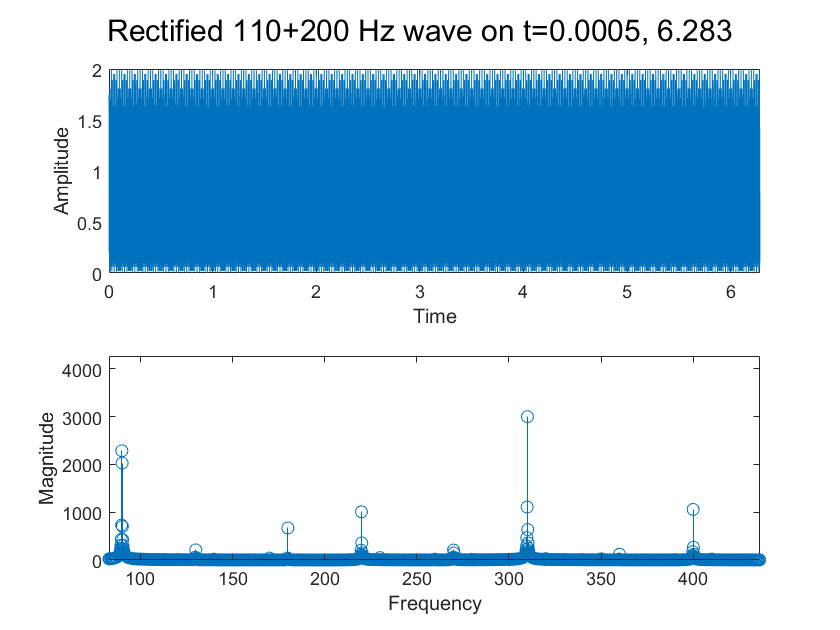


subplot(2,1,1);
plot(t, xt_rect);
xlim([0 2*pi])
xlabel("Time");
ylabel("Amplitude");

subplot(2,1,2);
stem(f_range, Xf);
xlabel("Frequency");
ylabel("Magnitude");
sgtitle("Rectified 110+200 Hz wave on t="+Ts+", "+N*Ts);

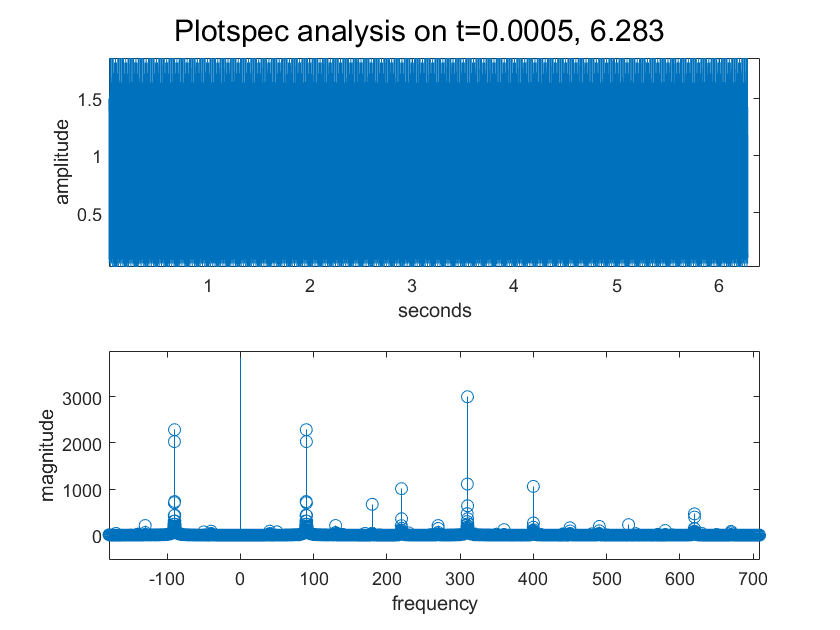


% Theres - through 2pi
figure(8);
plotspec(xt_rect, Ts);
sgtitle("Plotspec analysis on t=" + Ts + ", " + Ts*N);

(d) What frequencies will be present if x(t) is the sum of three sinusoids f1, f2, and f3?

The eight combinations are of each frequency, each being added and subtracted. 

Ex 2 -- Quantization 

Quantization of an input is another kind of common nonlinearity. The MatLab function quantalp.m quantizes a signal to the nearest element of a desired set. 

Let x be a random vector x=randn(1, n) of length n. Quantize x to the nearest [-3, -1, 1, 3].

(a) number of amplitude-1 results is 20-25x higher than amplitude-3 results (for both +/-)

(b) 

quant_steps = [-3 -1 1 3];
n = 1024;
x=randn(1,n);
x_quant=quantalph(x, quant_steps);

% part a 
[tally, bin] = groupcounts(x_quant)

tally =     19
   476
   516
    13


bin =     -3
    -1
     1
     3


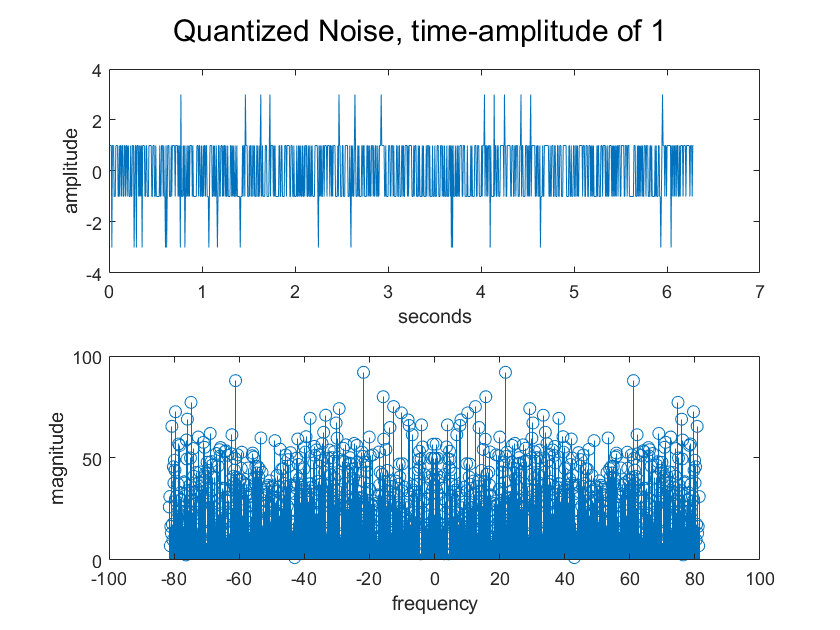


figure(9);
plotspec(x_quant, (2*pi)/1024);
sgtitle("Quantized Noise, time-amplitude of 1");

(c)  Prediction: exact same distribution

Result: distribution of quantization levels is much closer to equal for all. Mag-3s actually outnumber Mag-1s. 

quant_steps = [-3 -1 1 3];
n = 1024;
x=3*randn(1,n);
x_quant=quantalph(x, quant_steps);

% part a 
[tally, bin] = groupcounts(x_quant)

tally =    265
   262
   241
   256


bin =     -3
    -1
     1
     3


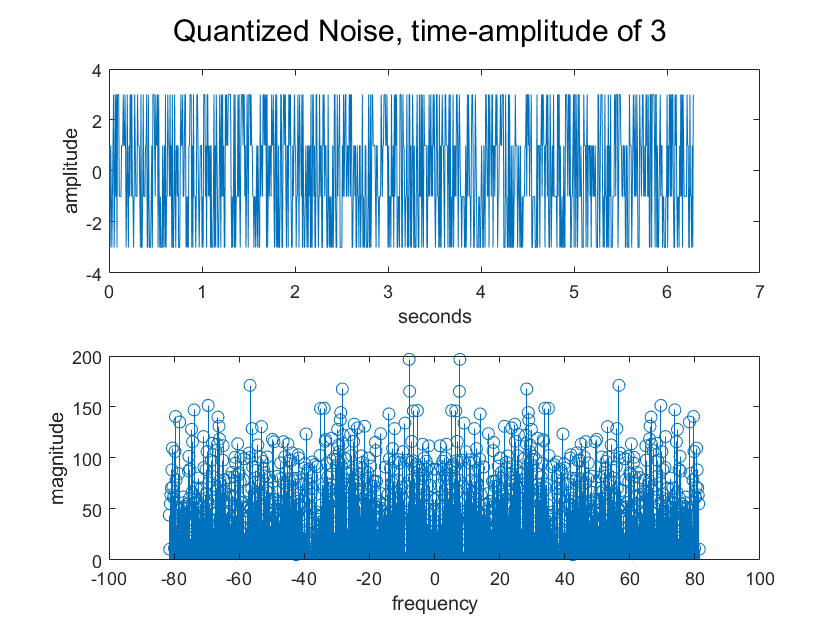


figure(10);
plotspec(x_quant, (2*pi)/1024);
sgtitle("Quantized Noise, time-amplitude of 3");

Ex 3 - Mixers 

One feature of most telco systems is the ability to change the frequency of the signal without changing its information content. For example, speech occurs in the range below ~8 kHz. To transmit, it is upconverted (*see SRD 2.3*) to radio frequencies at which the energy can easily propagate over long distances. At the receiver, it is downconverted (*SRD 2.6*) to the original f. 

Thus, the spectrum is shifted twice. Once way of accomplishing this kind of frequency shifting is to multiply the signal by a cosine wave. 

Ts = 1/10000;
t = Ts:Ts:0.5;
fc = 1000;
carrier = cos(2*pi*fc.*t);

(a) 

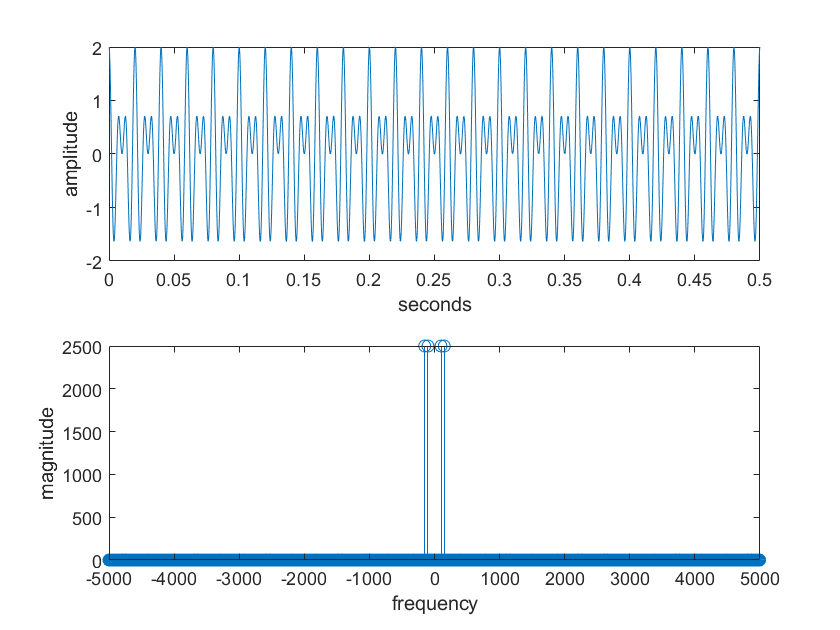

f1 = 100;
f2 = 150;
s1 = cos(2*pi*f1.*t);
s2 = cos(2*pi*f2.*t);

x = s1 + s2;
y_a = x.*carrier;

figure(11);
plotspec(x, Ts);

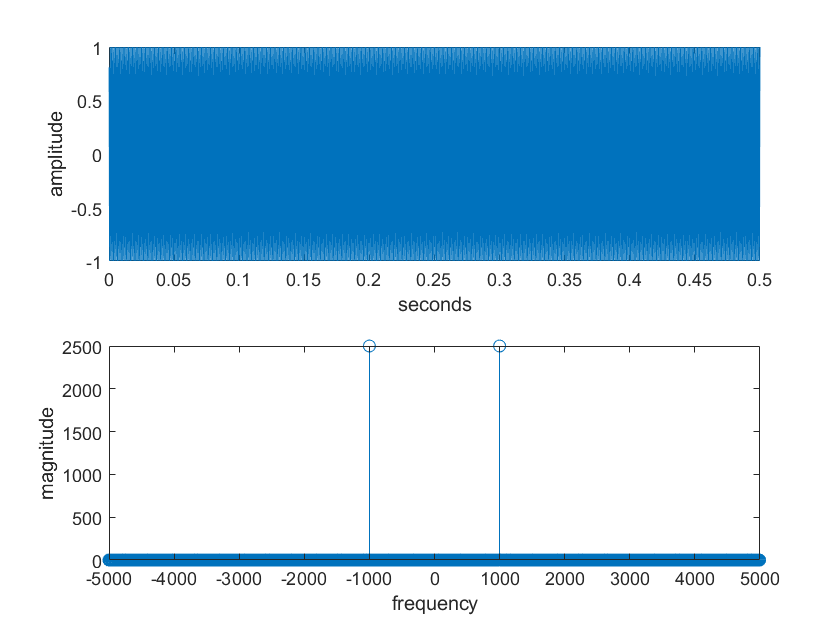

figure(12);
plotspec(carrier, Ts);

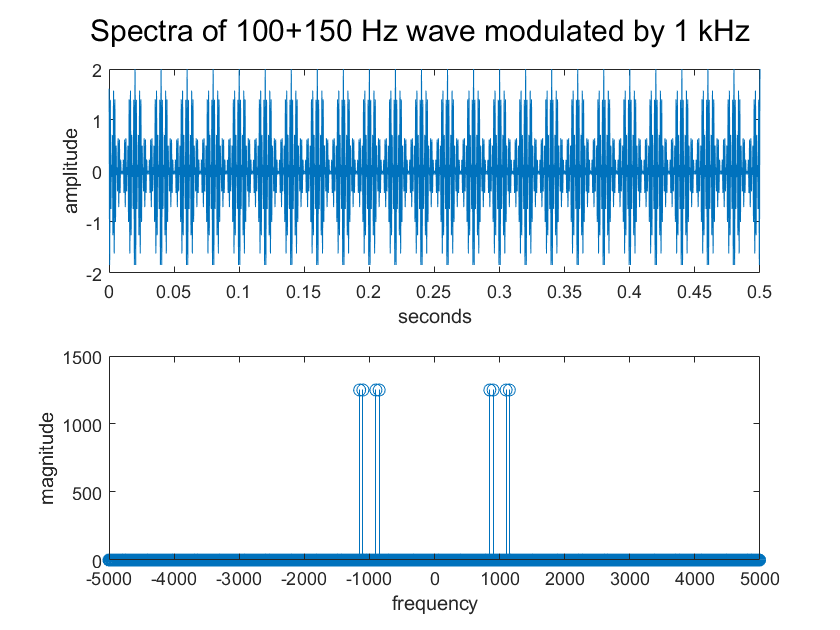

figure(13);
plotspec(y_a, Ts);
sgtitle("Spectra of 100+150 Hz wave modulated by 1 kHz");

(b) square wave with f = 150 Hz

f0 = 150

f0 = 150

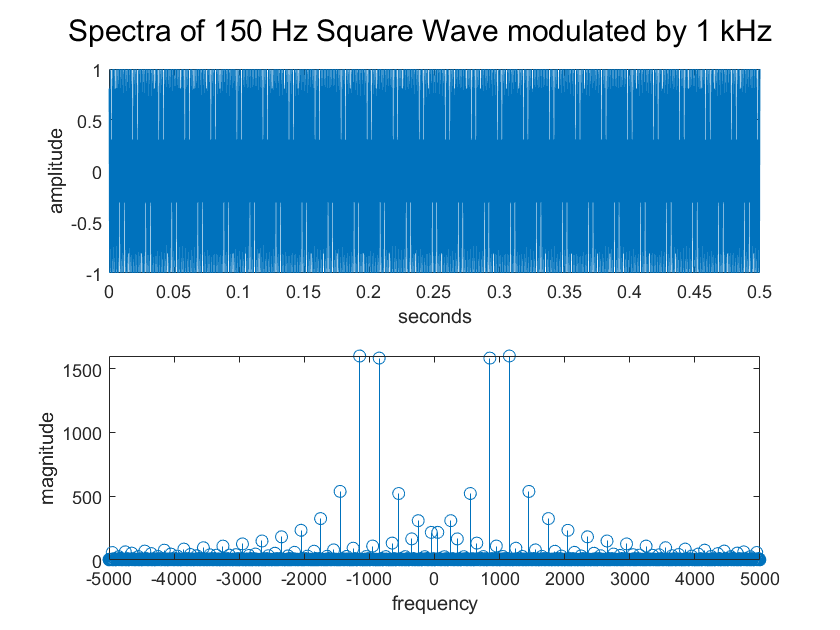

sqr = sign(cos(2*pi*f0.*t));
y_b = sqr.*carrier;
figure(14);
plotspec(y_b, Ts);
sgtitle("Spectra of 150 Hz Square Wave modulated by 1 kHz");

(c) noise signal with all energy below 300 Hz

Noise spectrum is completely filled with noise, even when the input is zero-padded. 

However, this presents an interesting question; should we take the reverse DFT to modulate in time domain?

After doing that, why are the spectra off center? Is it the carrier frequency or the lack of negative frequency content before taking DFT?

Answer: "`symflag`** — ****Symmetry type**

 `'nonsymmetric'`** (default) | **`'symmetric'`

Symmetry type, specified as `'nonsymmetric'` or `'symmetric'`. When `Y` is not exactly conjugate symmetric due to round-off error, `ifft(Y,'symmetric')` treats `Y` as if it were conjugate symmetric."

n300 = [randn(1, 300) zeros(300, 1)']

n300 =    -0.0272    0.6165    0.0150    0.6907    1.7191    0.6955   -0.1209   -0.7078    1.8418   -0.3818    1.0490    0.8553    0.6760    0.3899   -0.5687    0.7693   -0.1149    0.0197   -0.0324   -0.4526   -1.1911   -0.4185    1.2377    2.0043   -0.0400    0.6331    0.4333   -1.6543    0.1882   -0.9118   -1.5916   -0.7012    1.6813    0.0912   -1.0744    0.7162    0.4917   -0.3095    0.5593   -0.2843   -1.2746   -1.2579   -0.1366   -0.9584   -0.5242    0.0530    0.1448   -1.5655    0.3132   -0.0931


n300_t = ifft(n300, 600);
y_c = n300_t.*carrier(:, 1:600);

figure(15);
plotspec(n300_t, Ts);

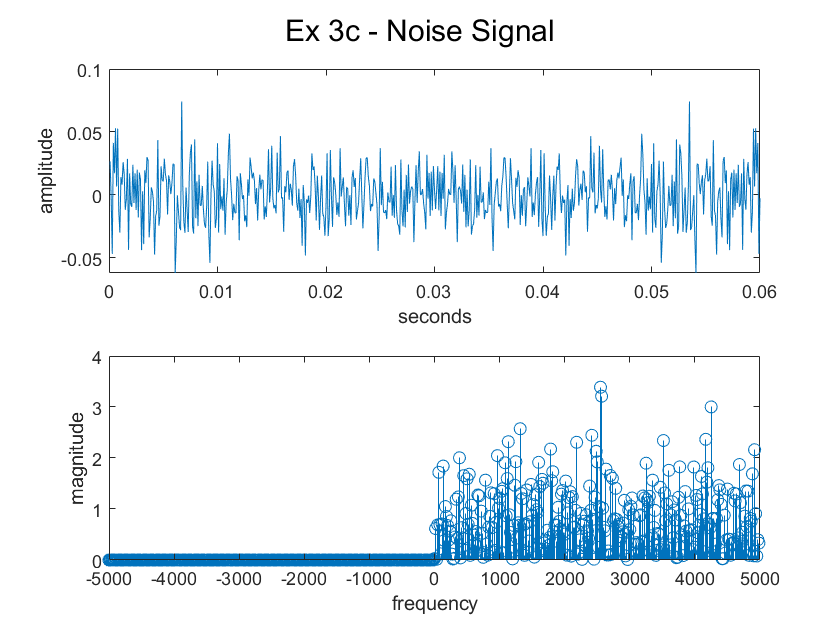

sgtitle("Ex 3c - Noise Signal");


figure(16);
plotspec(y_c, Ts);

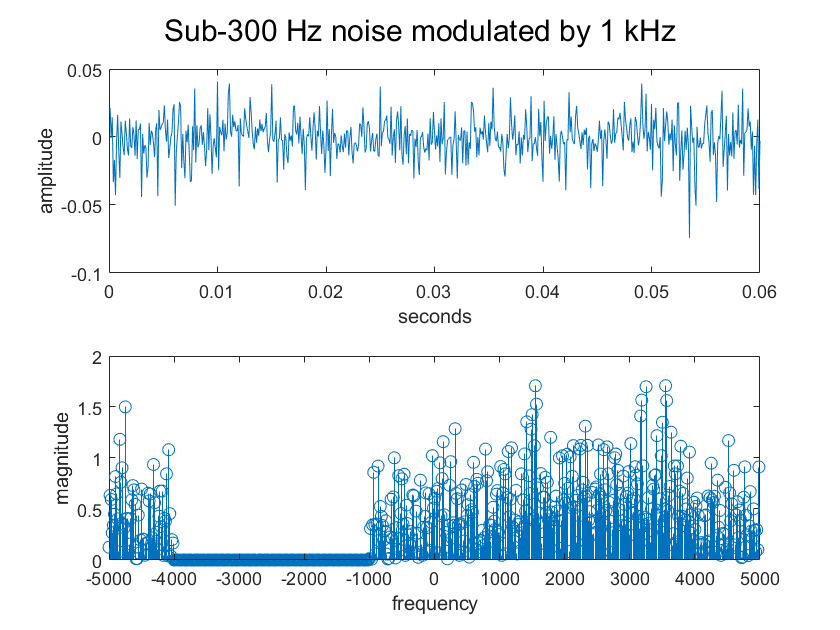

sgtitle("Sub-300 Hz noise modulated by 1 kHz");

(d) incorrect due to plotspec not reading spectra as one-sided (nonsymmetric) 

n2k_2300 = [zeros(2000, 1)'  randn(1, 300)  zeros(1700, 1)'];
n2k_23_t = ifft(n2k_2300, 5000) %nonsymmetric]

n2k_23_t =   -0.0047 + 0.0000i   0.0043 - 0.0019i  -0.0032 + 0.0035i   0.0015 - 0.0044i   0.0004 + 0.0046i  -0.0022 - 0.0040i   0.0036 + 0.0028i  -0.0043 - 0.0010i   0.0043 - 0.0008i  -0.0035 + 0.0024i   0.0021 - 0.0035i  -0.0004 + 0.0039i  -0.0013 - 0.0036i   0.0025 + 0.0026i  -0.0032 - 0.0012i   0.0032 - 0.0003i  -0.0026 + 0.0016i   0.0015 - 0.0024i  -0.0003 + 0.0026i  -0.0008 - 0.0022i   0.0016 + 0.0015i  -0.0019 - 0.0006i   0.0018 - 0.0003i  -0.0013 + 0.0009i   0.0007 - 0.0013i  -0.0001 + 0.0013i  -0.0003 - 0.0012i   0.0007 + 0.0009i  -0.0009 - 0.0006i   0.0011 + 0.0003i  -0.0011 + 0.0001i   0.0012 - 0.0005i  -0.0011 + 0.0009i   0.0008 - 0.0015i  -0.0002 + 0.0019i  -0.0006 - 0.0022i   0.0017 + 0.0020i  -0.0026 - 0.0013i   0.0033 + 0.0001i  -0.0034 + 0.0015i   0.0027 - 0.0030i  -0.0012 + 0.0042i  -0.0008 - 0.0047i   0.0029 + 0.0041i  -0.0046 - 0.0026i   0.0055 + 0.0004i  -0.0053 + 0.0021i   0.0040 - 0.0043i  -0.0018 + 0.0056i  -0.0008 - 0.0059i


y_d = n2k_23_t.*carrier(:, 1:5000);
figure(17);
plotspec(y_d, Ts);

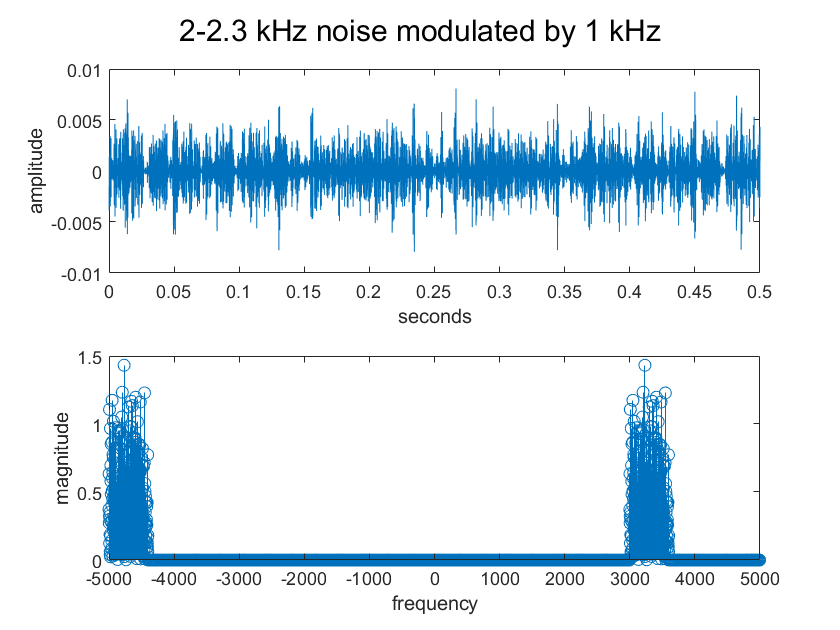

sgtitle("2-2.3 kHz noise modulated by 1 kHz")

(e) the input is a noise signal with all energy below 1500 Hz

unexpected results -- shouldn't we be seeing the copy from up to +/-1.5 kHz starting exactly at fc=1kHz (if not at f0=DC)? There's only one copy so then it should go from fc=1kHz to fc+f0=2.5kHz

 -> Changing Ts in plotspec to 1/6000 at least fixed the start -- noise still continues past 2.5kHz though

n_lt_1500 = [zeros(1500, 1)' randn(1, 3000) zeros(1500, 1)']

n_lt_1500 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


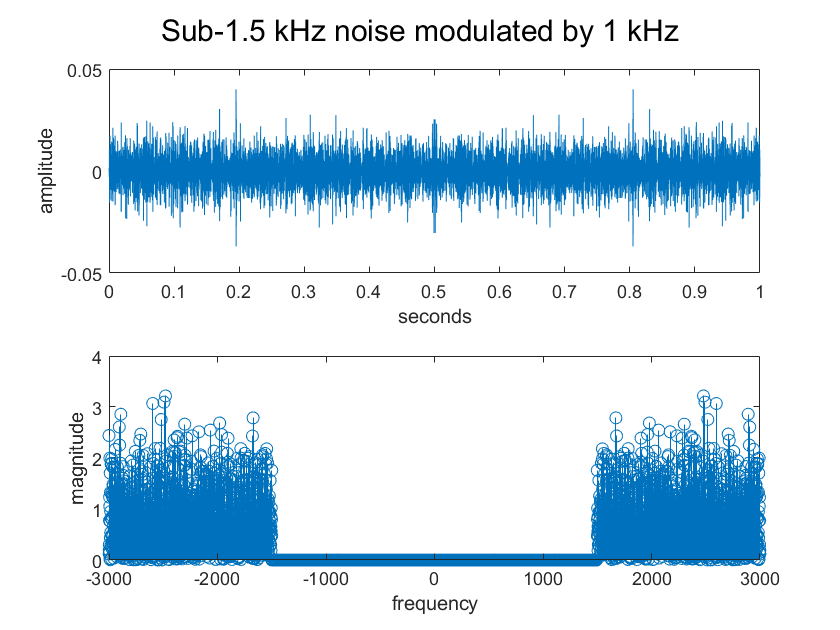

n_15_t = ifft(n_lt_1500, 6000, "symmetric");
figure(18);
plotspec(n_15_t, 1/6000);
sgtitle("Sub-1.5 kHz noise modulated by 1 kHz");